## Solve the PDE with homogeneous Neumann problem in 1D.

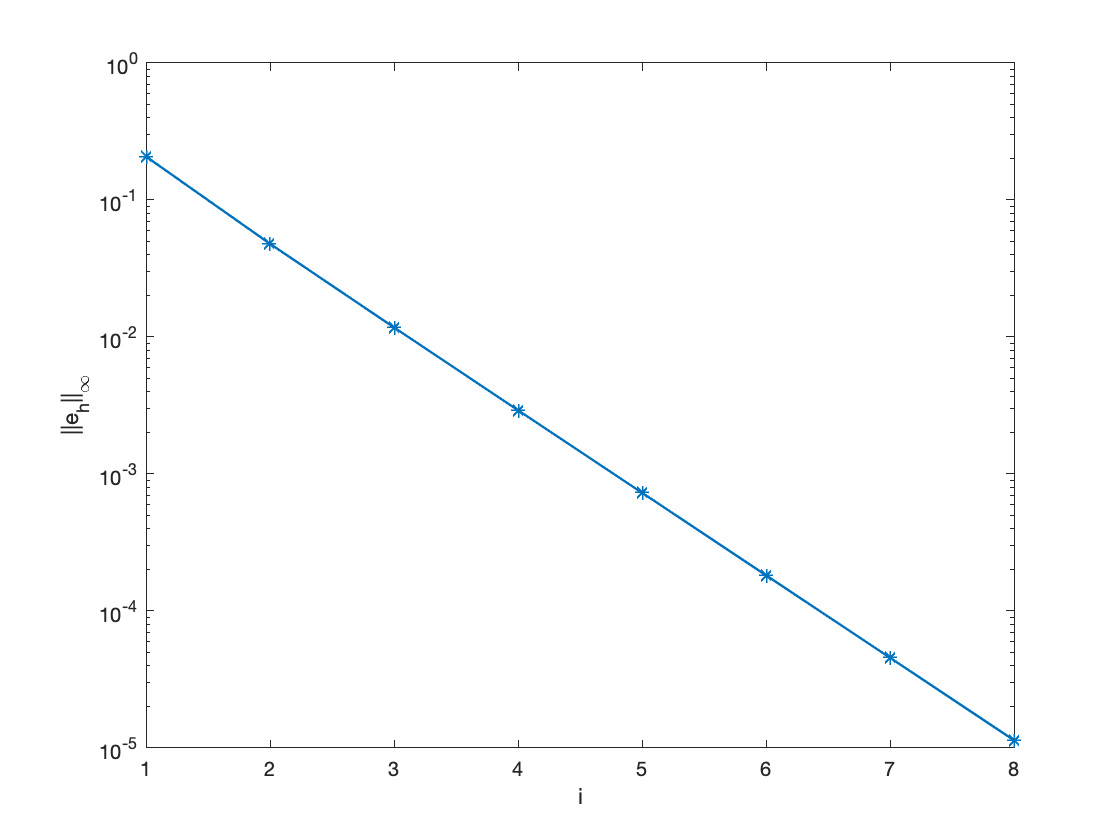

rhs_f = @(x) (1+pi^2)*cos(pi*x);
u_analytical = @(x) cos(pi*x);

norms = zeros(8, 1);

for i = 1:8
    n = 2^i;
    h = 1/n;
    x = -1:h:1;
    f = rhs(rhs_f, x');
    A = fdm1D_Neumann(n);
    u_h = A\f;
    u = u_analytical(x');
    curr_norm = norm(u - u_h, 'inf');
    norms(i) = curr_norm;
end

semilogy(norms, '*-', 'LineWidth', 1.2);
xlabel('i');
ylabel('||e_h||_\infty');

%%we except the scale factor equals to 4 because we used the second order
%%apprximate
norms(1:end-1)./norms(2:end)

ans =     4.3353
    4.0797
    4.0197
    4.0049
    4.0012
    4.0003
    4.0001


## Definition of functions part

Left hand side

function A = fdm1D_Neumann(n)
h = 1/n;
m = 2*n + 1;
o = ones(m, 1);
A = spdiags([-o 2*o -o], -1:1, m, m);
A(1,2) = -2;
A(end,end-1) = -2;
B = speye(m);
A = (1/(h^2))*A + B;
end

function f = rhs(func, x)
%discretizes the rhs for all nodes, bundaries included
%still not adapted to Neumann boundary conditions (for this, call
%applyHomogNeuRHS)
f = func(x);
end